## 差動二輪モデル

右タイヤの前進速度を$v_r$、左タイヤの前進速度を$v_l$とした時、ロボットの前進速度$v$と回頭速度$\omega$は、


$$\left\lbrack \begin{array}{c}
v\\
\omega 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1}{2} & \frac{1}{2}\\
\frac{1}{\mathrm{TR}} & -\frac{1}{\mathrm{TR}}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_r \\
v_l 
\end{array}\right\rbrack$$


となる。

現在のX位置$p_x$、Y位置$p_y$、ヨー角$\theta$とすると、


$$p_{x\_\textrm{next}} =p_x +\Delta t\cdot v\cdot \cos \theta$$



$$p_{y\_\textrm{next}} =p_y +\Delta t\cdot v\cdot \sin \theta$$



$$\theta_{\textrm{next}} =\theta +\Delta t\cdot \omega$$


## 初期設定

パラメーター

TR = 0.5;

時間設定

delta_time = 0.1;
start_time = 0;
end_time = 10;
time_line = start_time:delta_time:end_time;

ログ設定

px_log = zeros(size(time_line));
py_log = zeros(size(time_line));
theta_log = zeros(size(time_line));

## シミュレーション実行

初期化

log_index = 1;

px = 0;
py = 0;
theta = 0;

繰り返し処理

for i = time_line

    vr = 1;
    vl = 0.5;

    v = (vr + vl) / 2;
    omega = (vr - vl) / TR;

    px = px + delta_time * v * cos(theta);
    py = py + delta_time * v * sin(theta);
    theta = theta + delta_time * omega;

    % ログ
    px_log(log_index) = px;
    py_log(log_index) = py;
    theta_log(log_index) = theta;

    log_index = log_index + 1;
end


## 結果の確認

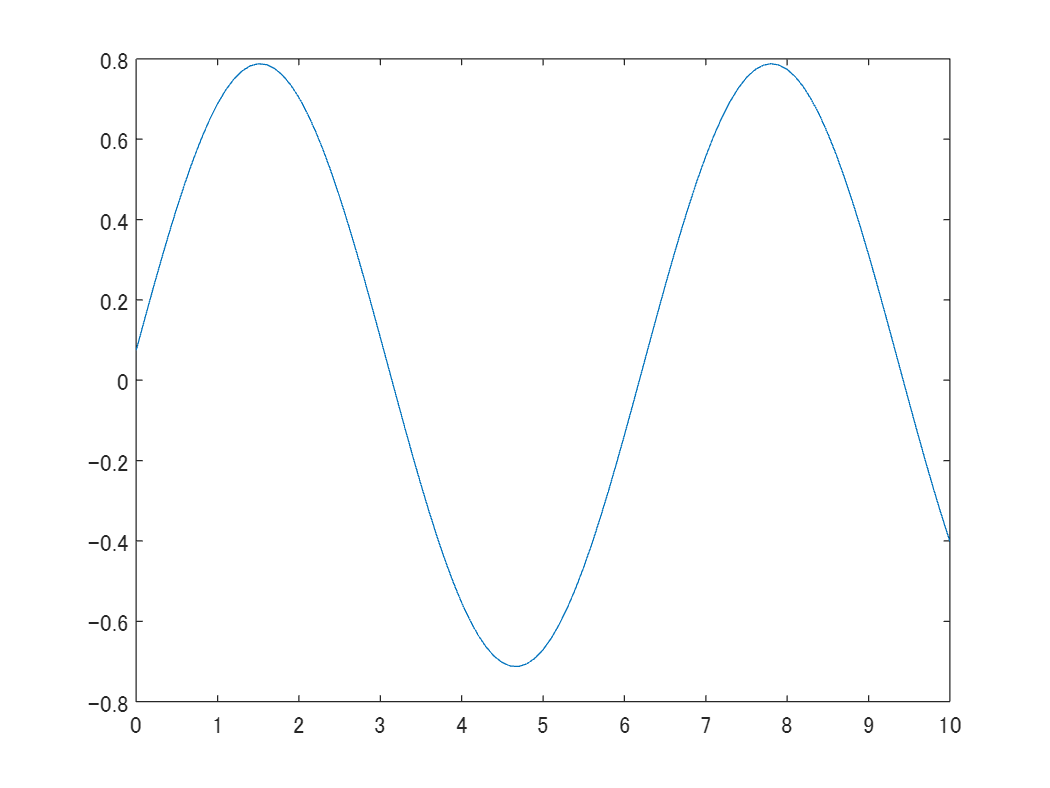

plot(time_line, px_log);

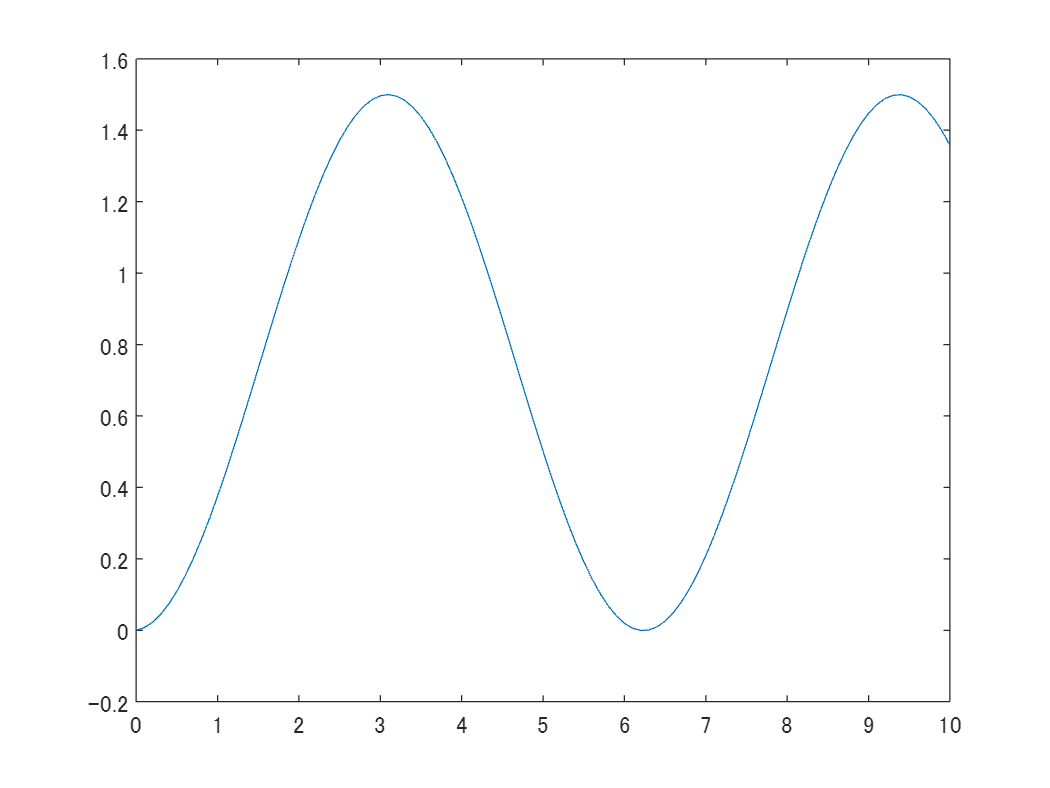

plot(time_line, py_log);

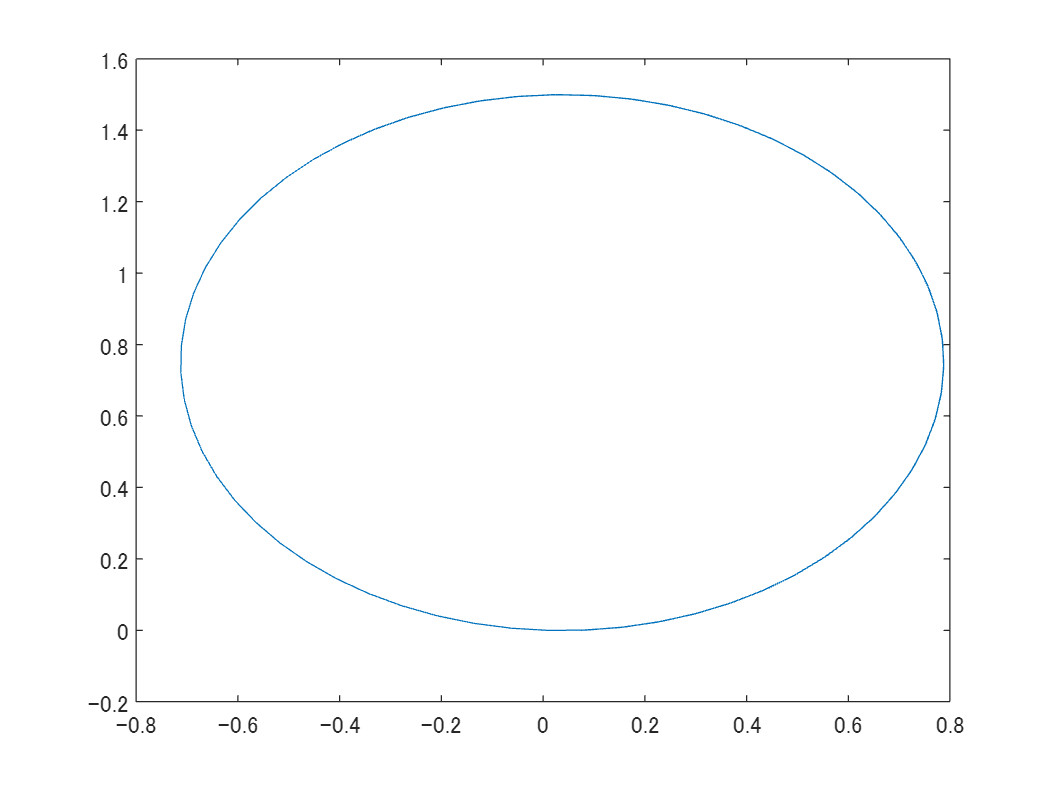

plot(px_log, py_log);

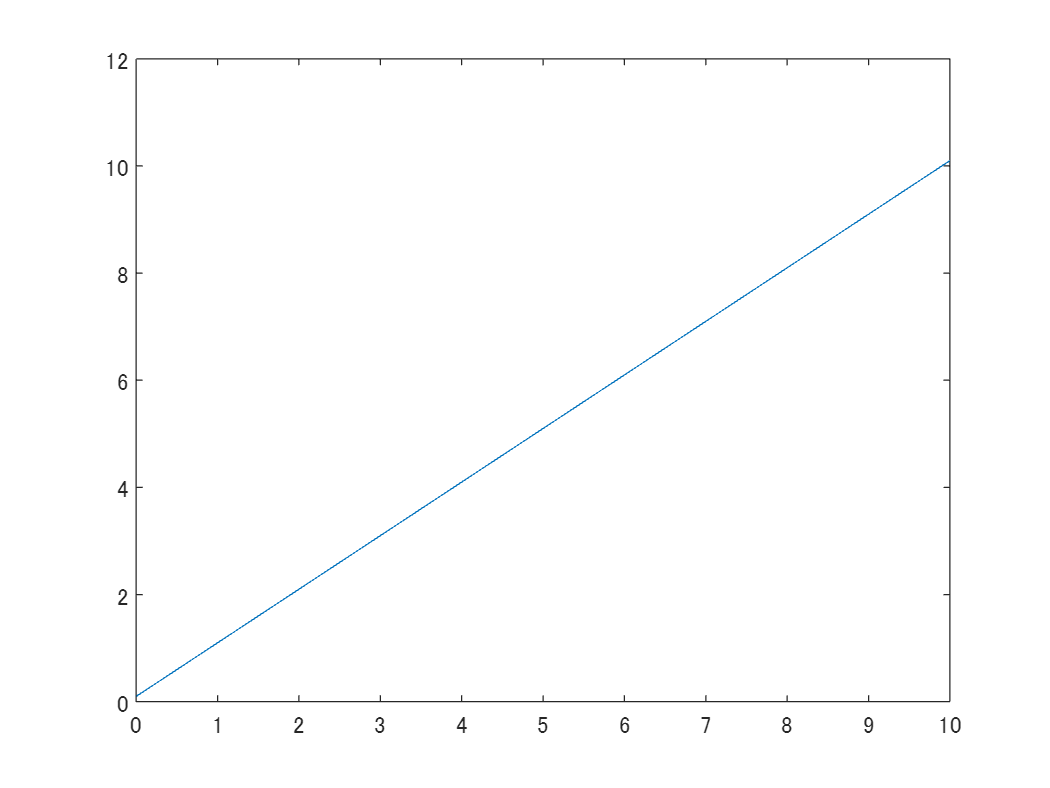

plot(time_line, theta_log);